clc
clear
close all

% Define transfer function
num = [5];
den = [1 3 5];
G = tf(num,den);

disp('Transfer Function:')

Transfer Function:


G


G =
 
        5
  -------------
  s^2 + 3 s + 5
 
Continuous-time transfer function.


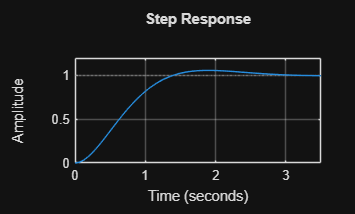


% Step response
figure
step(G)
grid on
title('Step Response')

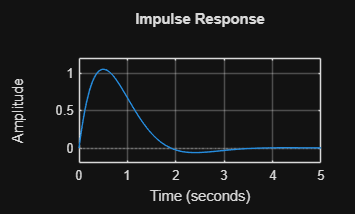


% Impulse response
figure
impulse(G)
grid on
title('Impulse Response')


% System characteristics
info = stepinfo(G)

info = struct with fields:
         RiseTime: 0.9127
    TransientTime: 2.6881
     SettlingTime: 2.6881
      SettlingMin: 0.9149
      SettlingMax: 1.0583
        Overshoot: 5.8316
       Undershoot: 0
             Peak: 1.0583
         PeakTime: 1.9035



% Poles and zeros
p = pole(G)

p =   -1.5000 + 1.6583i
  -1.5000 - 1.6583i


z = zero(G)


z =

  0×1 empty double column vector

